# **Lab 2**

**Experminet 2.1)**

**Part 1)**

a)

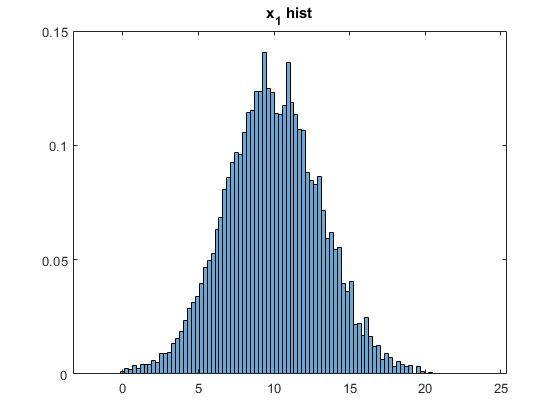

mean = 10;
var = 10;
sample_num = 10000;
x1 = sqrt(var) * randn(sample_num,1) + mean;
histogram(x1,100,'Normalization',"pdf");
title('x_1 hist')

b)

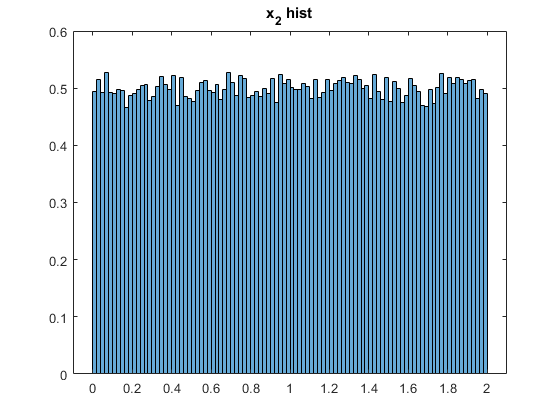

b = 0;
a = 2;
sample_num2 = 100000;
x2 = a*rand(sample_num2,1)+b;
histogram(x2,100,'Normalization',"pdf");
title('x_2 hist')

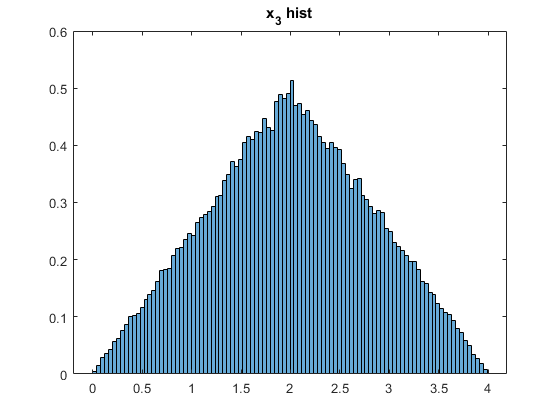

x3 = x2 + [0 ; x2(1:end-1)];
histogram(x3,100,'Normalization',"pdf");
title('x_3 hist')

As we know pdf of random variable formed by summation of 2 independent random variables is defined by convolution of their pdf. In conclusion convolution of 2 pulse(pdf of Uniform Dist.) is a triangle.

c)

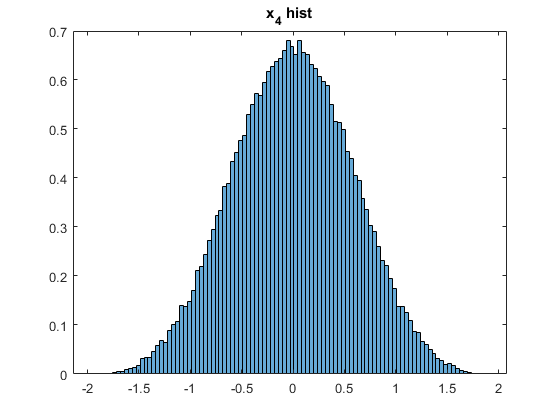

b = -0.5;
a = 1;
y = a*rand(sample_num2,4)+b;
x4 = y(:,1)+y(:,2)+y(:,3)+y(:,4);
histogram(x4,100,'Normalization',"pdf");
title('x_4 hist')

As we can observe, the shape of the pdf is getting close to gaussian distribution. This fact is based on CLT(Central Limit Theorem) that states summation of large number of random variable converges to gaussian distribution.

**Experiment 2.2**

**Part 1)**

a)

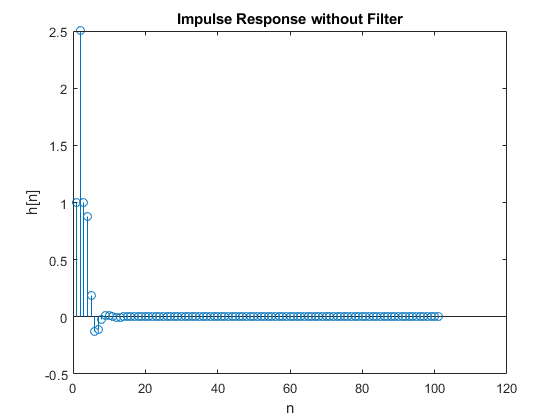

n = 101;
y = zeros(n,1);
x = zeros(n,1);
x(1) = 1;
for i = 1:n 
    if i > 3 
        y(i) = 0.5*y(i-1) - 0.25*y(i-2) +x(i) +2*x(i-1) +x(i-3);
    elseif i == 3
        y(i) = 0.5*y(i-1) - 0.25*y(i-2) +x(i) +2*x(i-1); 
    elseif i == 2
        y(i) = 0.5*y(i-1) +x(i) +2*x(i-1); 
    elseif i == 1
        y(i) =  x(i); 
    end
end
stem(1:n , y)
xlabel('n');
ylabel('h[n]');
title('Impulse Response without Filter')

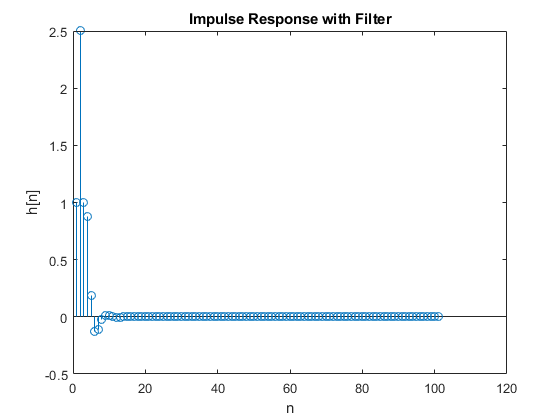

h = filter([1 2 0 1],[1 -0.5 0.25],x);
stem(1:n,h);
xlabel('n');
ylabel('h[n]');
title('Impulse Response with Filter')

**Part 2)**

a) the corr_m function is included in the .m file.

b)

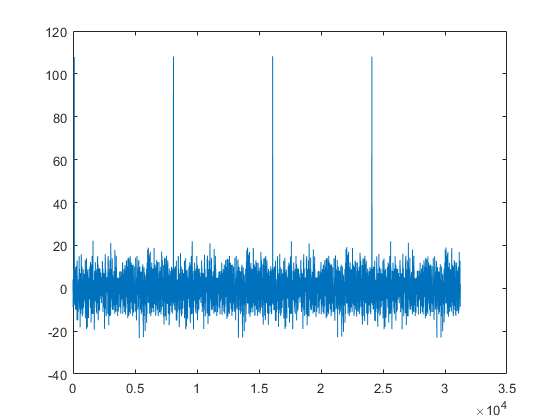

RP = load("PacketsAndHeader.mat");
Header = RP.hdr_smpl;
Signal = RP.rx_smpl;
HScorr = corr_m(Header,Signal);

max_vals = HScorr(HScorr > 100);
indx1 = find(HScorr==max_vals(1));
indx2 = find(HScorr==max_vals(2));
NumOfSamples = indx2-indx1;
NumOfSymbols = NumOfSamples/8;
Fs = 10e6;
Ts = 1/Fs;
C = 3e8;
TimeSpacing = Ts*NumOfSamples;
Distance = C*(indx1-1)*Ts;
disp("Distance: (m)");

Distance: (m)


disp(Distance);

        3000



disp("Number of Symbols:");

Number of Symbols:


disp(NumOfSymbols);

        1000



disp("Packet Time: (s)");

Packet Time: (s)


disp(TimeSpacing)

   8.0000e-04



####     Experiment 2.3

part1)

a)

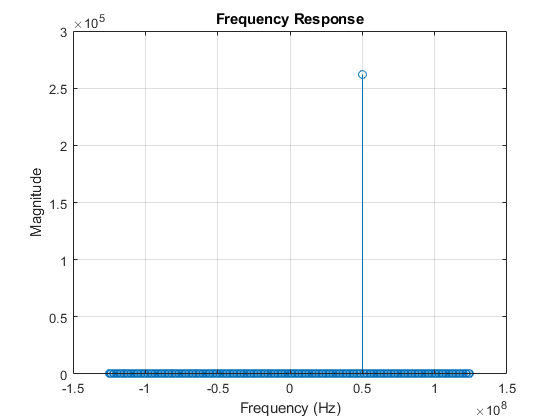

Ratio=
    51



A = 2;
N = 256;
f0= 250*(51/256)*1e6;
fft_plot(A,N,f0);

b)

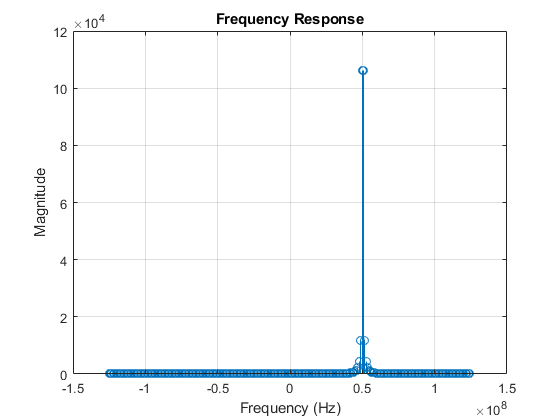

Ratio=
   51.5000



A = 2;
N = 256;
f0= 250*(51.5/256)*1e6;
fft_plot(A,N,f0);

c)

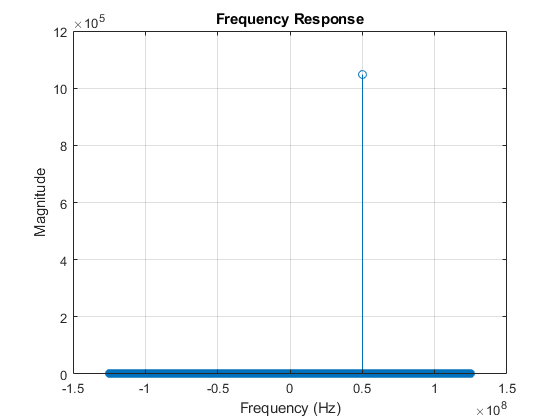

Ratio=
   102



A = 2;
N = 512;
f0= 250*(51/256)*1e6;
fft_plot(A,N,f0);

d)

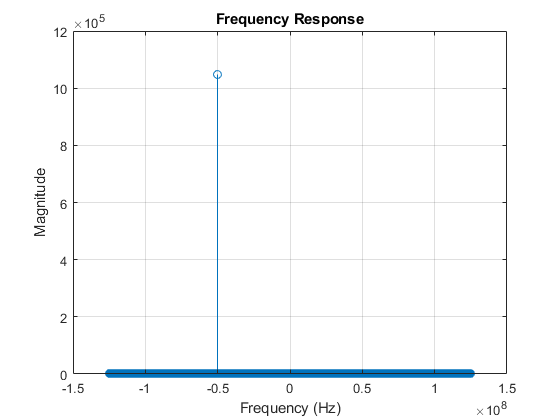

Ratio=
  -102



A = 2;
N = 512;
f0= -250*(51/256)*1e6;
fft_plot(A,N,f0);

e)

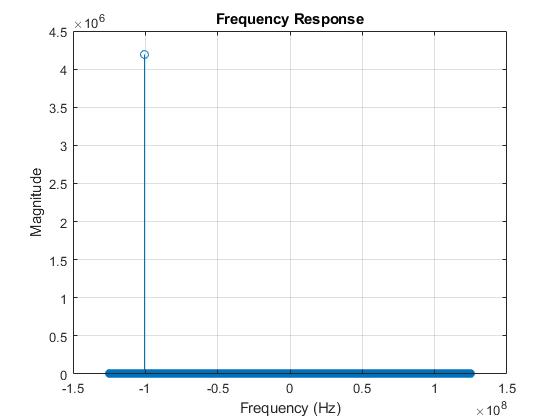

Ratio=
   306



A = 4;
N = 512;
f0= 250*(153/256)*1e6;
fft_plot(A,N,f0);

h)

Spectral leakage is observed in the second plot due to the resolution of FFT and existing frequencies. 

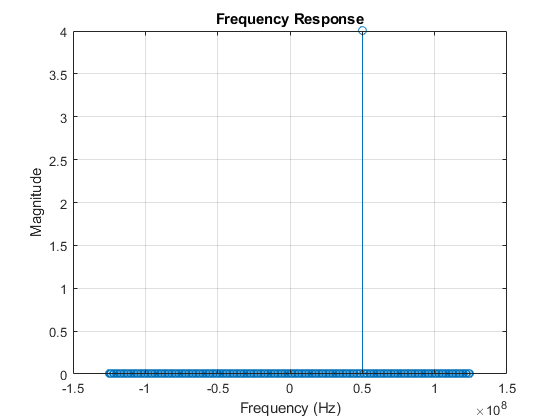

Ratio=
    51



A = 2;
N = 256;
f0= 250*(51/256)*1e6;
fft_plot_A2(A,N,f0);

b)

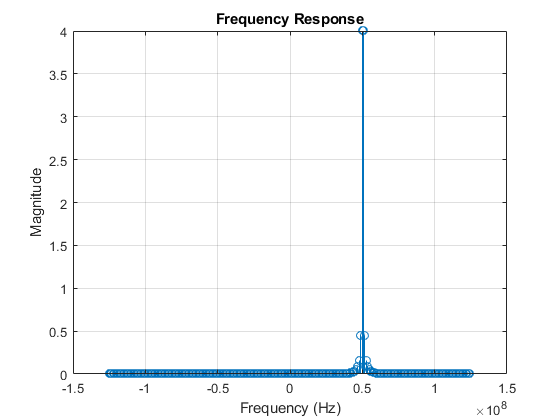

Ratio=
   51.5000



A = 2;
N = 256;
f0= 250*(51.5/256)*1e6;
fft_plot_A2(A,N,f0);

c)

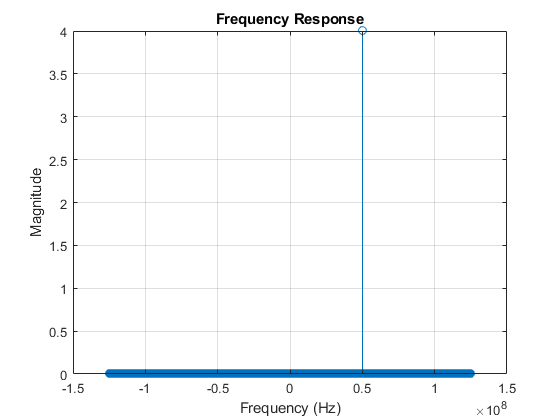

Ratio=
   102



A = 2;
N = 512;
f0= 250*(51/256)*1e6;
fft_plot_A2(A,N,f0);

d)

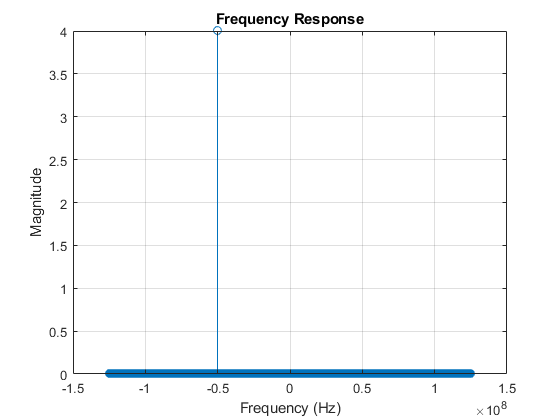

Ratio=
  -102



A = 2;
N = 512;
f0= -250*(51/256)*1e6;
fft_plot_A2(A,N,f0);

e)

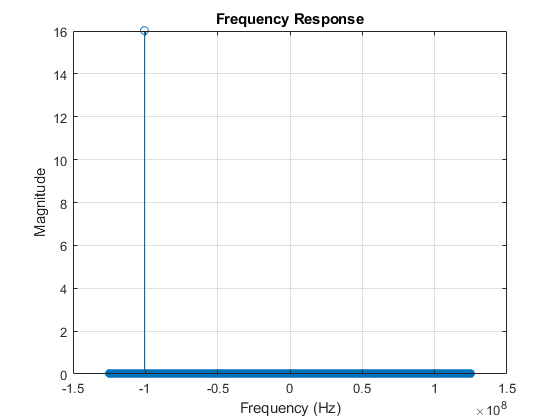

Ratio=
   306



A = 4;
N = 512;
f0= 250*(153/256)*1e6;
fft_plot_A2(A,N,f0);

d)

as the number of points is increased, the frequency resolution increases and more frequencies are observable in spectrum if existing. 

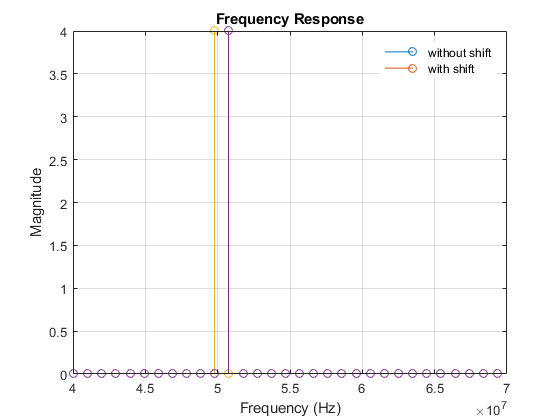

A = 2;
N = 256;
f0= 250*(51/256)*1e6;
fft_plot_offset(A,N,f0);

z)

A = 2;
N = 256;
f0= 250*(51/256)*1e6;
Power_Calc_Time_Dom(A,N,f0);

Power calculated in time domain :
     4



Power_Calc_Freq_Dom(A,N,f0);

Power calculated in frequency domain :
     4



as it is observed, the power calculated in time domain is equal to the one calculated in frequency domain. 

r)

a)

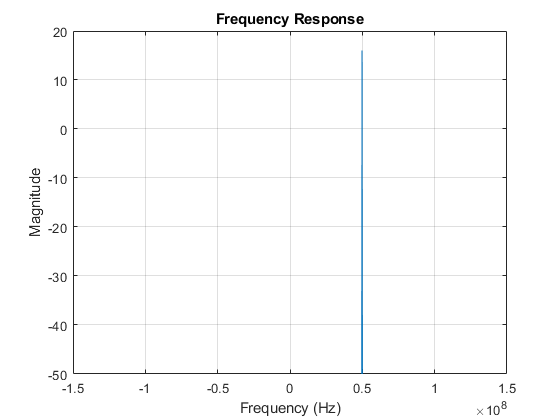

A = 2;
N = 256;
f0= 250*(51/256)*1e6;
fft_plot_dbm(A,N,f0);

b)

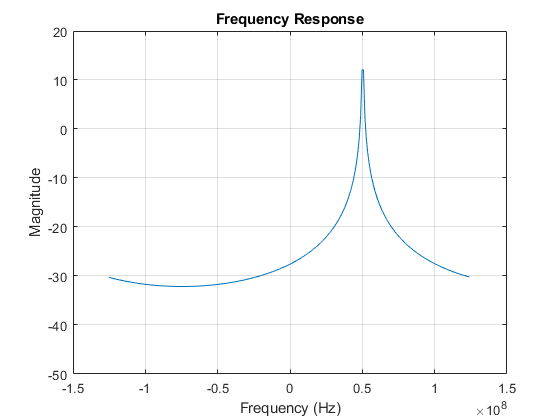

A = 2;
N = 256;
f0= 250*(51.5/256)*1e6;
fft_plot_dbm(A,N,f0);